# Course: Image Processing and Pattern Recognition Lab

Sem: WS20/21

Date: 

Group Id: Carl Friedrich Gauß

Group Members: 

1. Prashasti Sahu

2. Friedrich Mütschele

Description: This MATLAB file contains the code implemented as part of LAB 1 - Exercise 01

`Hint: To print your result to the output window, don't end your code with a semi colon  `

**Task 1 **Generate a 3x3 random integer matrix with name **"rand_mat"** whose elements range from 5 to 20.

rand_mat = randi([5,20], [3,3])

rand_mat =     17    19    16
     8    14    14
    12    18     8


**Task 2 **Generate a 3x1 Identity matrix with name **"ident_mat" **and multiply the transpose of **"ident_mat"** with **"rand_mat"**. Name the resultant Matrix as **"t2_result"**.

Note: **t2_result** should be a 1x3 matrix i.e. 1 row and 3 columns

ident_mat = eye(1,3)

ident_mat =      1     0     0



t2_result = rand_mat * transpose(ident_mat)

t2_result =     17
     8
    12


**Task 3 **Generate exactly 10 real number values that are equally spaced between 1 to 9 and store it in a variable by name **"t3_result"**.

t3_result = linspace(1,9,10)

t3_result =     1.0000    1.8889    2.7778    3.6667    4.5556    5.4444    6.3333    7.2222    8.1111    9.0000


% Question: Between 1 and 9 includes 1 and 9 or not?

**Task 4** Store the first two elements and last two elements of the matrix **"t3_result" **to** "t4_result".**

t4_result = [t3_result(1:2) t3_result(9:10)]

t4_result =     1.0000    1.8889    8.1111    9.0000


**Task 5 **Delete the thrid column of matrix **"t4_result".**

t4_result = t4_result([1:2 4])

t4_result =     1.0000    1.8889    9.0000


%shall we restore to t4_result?

**Task 6 **Generate a 3x3 matrix whose first row is **"t4_result";** second row elements are 10,100,0.5 in ascending order and third row elements are squares of first row elements respectively. Name the resultant matrix as **"t6_result"**

t6_result = [t4_result.' sort([10,100,0.5]).' t4_result.'.^2]

t6_result =     1.0000    0.5000    1.0000
    1.8889   10.0000    3.5679
    9.0000  100.0000   81.0000


**Task 7** As part of this task, you are given a MATLAB data file called t7_struct.mat. Load the data file into MATLAB and assign it to a variable by name t7_struct. This data file contains a matlab data structure called **dataset,** which has two fields inside it namely "data" and "labels". ***t7_struct.dataset.data*** is a 15 x 8 matrix whose row values represent multiples from 2 to 9 of a number present the corresponding row of ***t7_struct.dataset.labels ***

your task it to implement a code to dynamically extract all rows elements that correspond to multiples of numbers 7,3,5,2,4 from ***t7_struct.dataset.data***

t7_struct = load("t7_struct.mat")

t7_struct = struct with fields:
    dataset: [1×1 struct]


t7_struct.dataset.data

ans =      4     6     8    10    12    14    16    18
     6     9    12    15    18    21    24    27
     8    12    16    20    24    28    32    36
    10    15    20    25    30    35    40    45
    12    18    24    30    36    42    48    54
    14    21    28    35    42    49    56    63
    16    24    32    40    48    56    64    72
    18    27    36    45    54    63    72    81
    10    15    20    25    30    35    40    45
     6     9    12    15    18    21    24    27


t7_struct.dataset.labels

ans =      2
     3
     4
     5
     6
     7
     8
     9
     5
     3


for i=1:15
    if t7_struct.dataset.labels(i) == 7||t7_struct.dataset.labels(i) ==3||t7_struct.dataset.labels(i) ==5||t7_struct.dataset.labels(i) ==2||t7_struct.dataset.labels(i) ==4
       t7_struct.dataset.data(i,:) 
    end
end

ans =      4     6     8    10    12    14    16    18


ans =      6     9    12    15    18    21    24    27


ans =      8    12    16    20    24    28    32    36


ans =     10    15    20    25    30    35    40    45


ans =     14    21    28    35    42    49    56    63


ans =     10    15    20    25    30    35    40    45


ans =      6     9    12    15    18    21    24    27


ans =      4     6     8    10    12    14    16    18


ans =      8    12    16    20    24    28    32    36


ans =     14    21    28    35    42    49    56    63


**Task 8** You are given three linear equations of the form a1x + b1y + c1z = 7;  a2x + b2y + c2z = 4; a3x+b3y+c3z=-10; The values of variable a1, a2,a3 are 1,-2,3. The values of variables b1, b2 b3 are 2,1,1 and values of c1, c2 and c3 are -3, 2, -2 respectively. Implement a code to solve the above system equations. Also plot these three line equations and show the result. 

a = [1,-2,3].';
b = [2,1,1].';
c = [3,3,3].';
B = [7,4,10].'

B =      7
     4
    10


A = [a,b,c]

A =      1     2     3
    -2     1     3
     3     1     3



X = linsolve(A,B)

X =     1.2000
   -0.6000
    2.3333


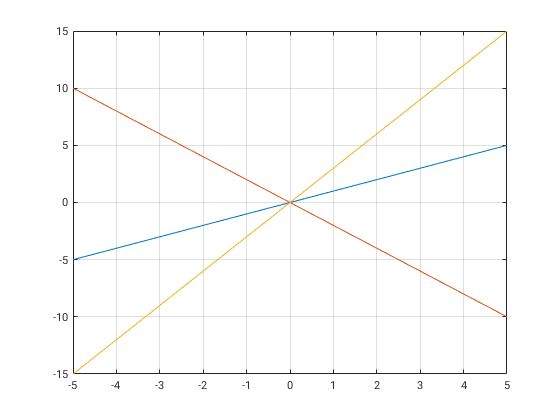


x = -5:0.1:5;

y1 = x*A(1);
y2 = x*A(2);
y3 = x*A(3);

figure(1)
plot(x, y1)
hold on
plot(x, y2)
plot(x, y3)
hold off
grid